# Calculate ERPs

cfg = [];
% Face
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'nmf') | strcmp({ft_data1.hdr.orig.event.type},'mnf')| strcmp({ft_data1.hdr.orig.event.type},'mmf') | strcmp({ft_data1.hdr.orig.event.type},'nnf'));
erp_face = ft_timelockanalysis(cfg, ft_data1);

the input is raw data with 123 channels and 1233 trials
the call to "ft_selectdata" took 0 seconds


% House
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'nmh') | strcmp({ft_data1.hdr.orig.event.type},'mnh')| strcmp({ft_data1.hdr.orig.event.type},'mmh') | strcmp({ft_data1.hdr.orig.event.type},'nnh'));
erp_house = ft_timelockanalysis(cfg, ft_data1);

% Expectation (Face)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmf') | strcmp({ft_data1.hdr.orig.event.type},'nnf'));
erp_expected_f = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnf') | strcmp({ft_data1.hdr.orig.event.type},'nmf'));
erp_unexpected_f = ft_timelockanalysis(cfg, ft_data1);

% Repeatition (Face)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmf') | strcmp({ft_data1.hdr.orig.event.type},'nmf'));
erp_repeat_f = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnf') | strcmp({ft_data1.hdr.orig.event.type},'nnf'));
erp_alternate_f = ft_timelockanalysis(cfg, ft_data1);

% Expectation (House)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmh') | strcmp({ft_data1.hdr.orig.event.type},'nnh'));
erp_expected_h = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnh') | strcmp({ft_data1.hdr.orig.event.type},'nmh'));
erp_unexpected_h = ft_timelockanalysis(cfg, ft_data1);

% Repeatition (House)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmh') | strcmp({ft_data1.hdr.orig.event.type},'nmh'));
erp_repeat_h = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnh') | strcmp({ft_data1.hdr.orig.event.type},'nnh'));
erp_alternate_h = ft_timelockanalysis(cfg, ft_data1);


% Expectation (Inverse Face)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmif') | strcmp({ft_data1.hdr.orig.event.type},'nnif'));
erp_expected_if = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnif') | strcmp({ft_data1.hdr.orig.event.type},'nmif'));
erp_unexpected_if = ft_timelockanalysis(cfg, ft_data1);

% Repeatition (Inverse Face)
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mmif') | strcmp({ft_data1.hdr.orig.event.type},'nmif'));
erp_repeat_if = ft_timelockanalysis(cfg, ft_data1);
cfg.trials = find(strcmp({ft_data1.hdr.orig.event.type},'mnif') | strcmp({ft_data1.hdr.orig.event.type},'nnif'));
erp_alternate_if = ft_timelockanalysis(cfg, ft_data1);

# Face vs. House

**Visualize ERPs on the whole scalp**

ft_data1.elec.coordsys = 'eeglab';
cfg = [];
cfg.elec = ft_data1.elec;   
layout = ft_prepare_layout(cfg);

creating layout from cfg.elec
creating layout for eeg1005 system
the call to "ft_prepare_layout" took 5 seconds



cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
ft_multiplotER(cfg, erp_face, erp_house);

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 3 seconds


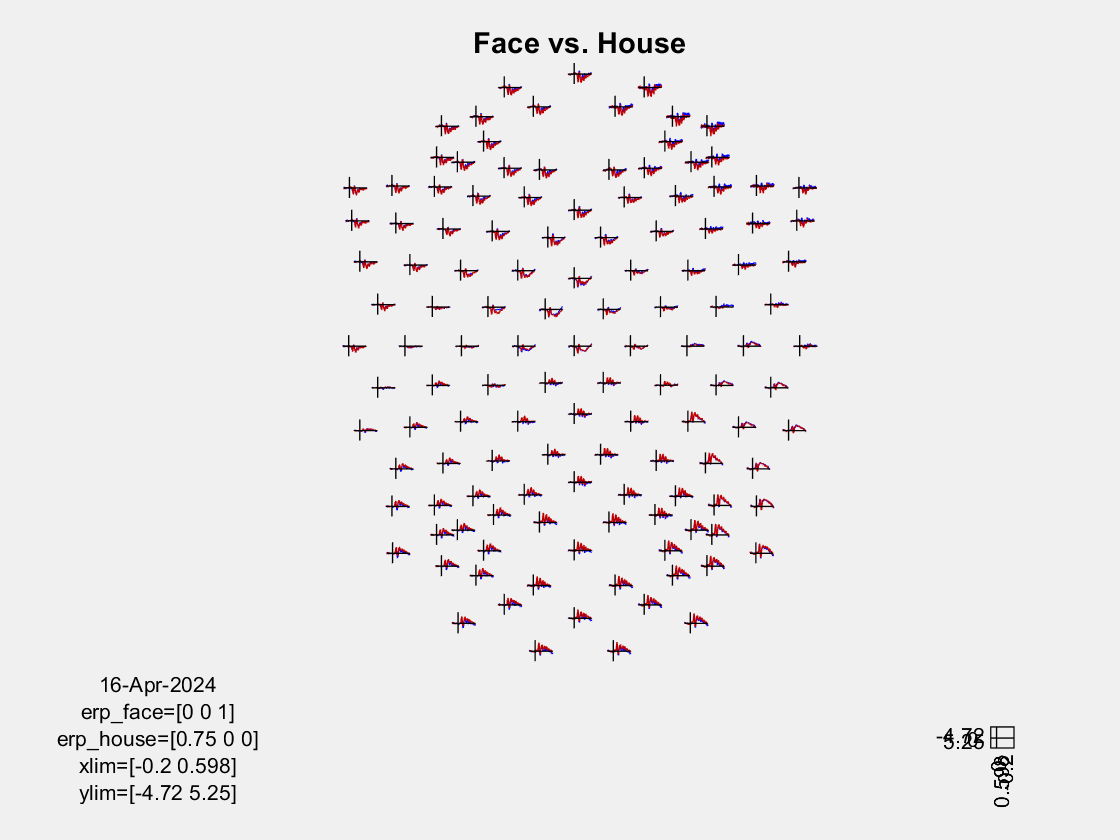

title('Face vs. House')

**Occipital -> P1 (Detection of Visual Stimulus)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


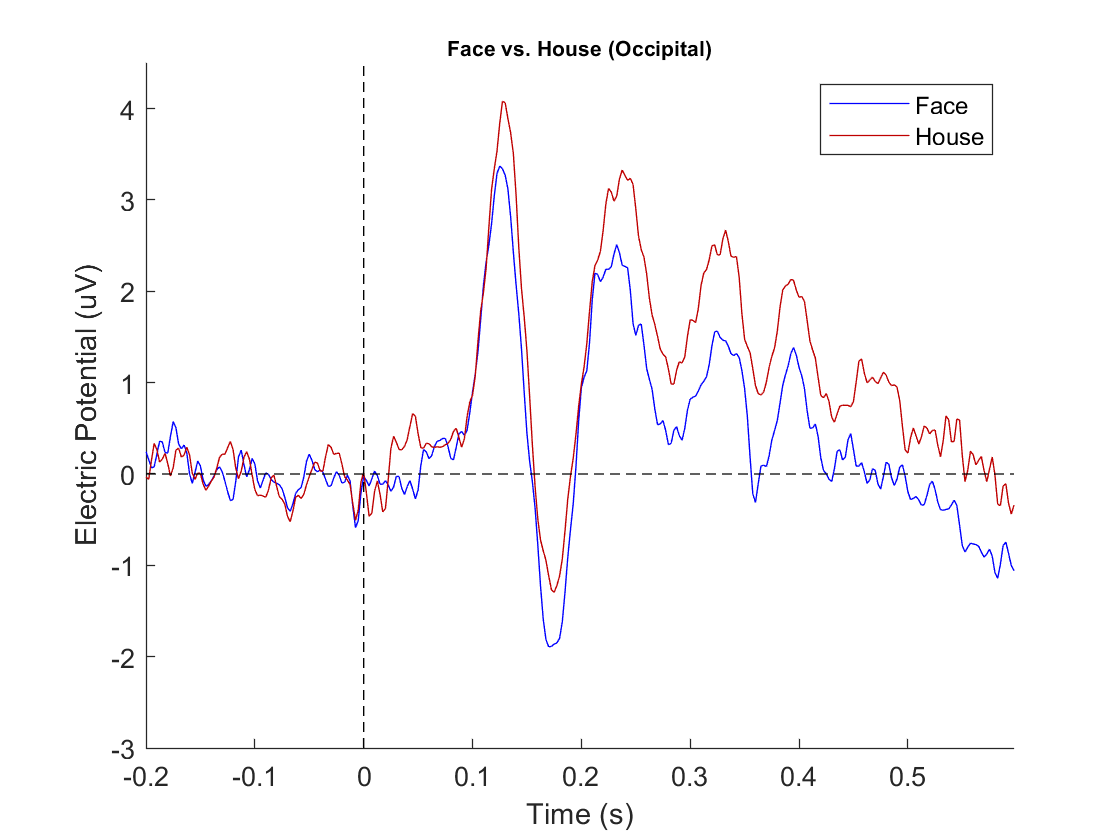

occip = {'O1', 'O2', 'Oz', 'POz','POO2','POO9h','OI1h','OI2h','POO10h'};
plot_ERP_func(occip,erp_face,erp_house,'Face','House','Face vs. House (Occipital)',[-3 4.5]);

**Occipital-Temporal -> N170 (Detection of a face)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


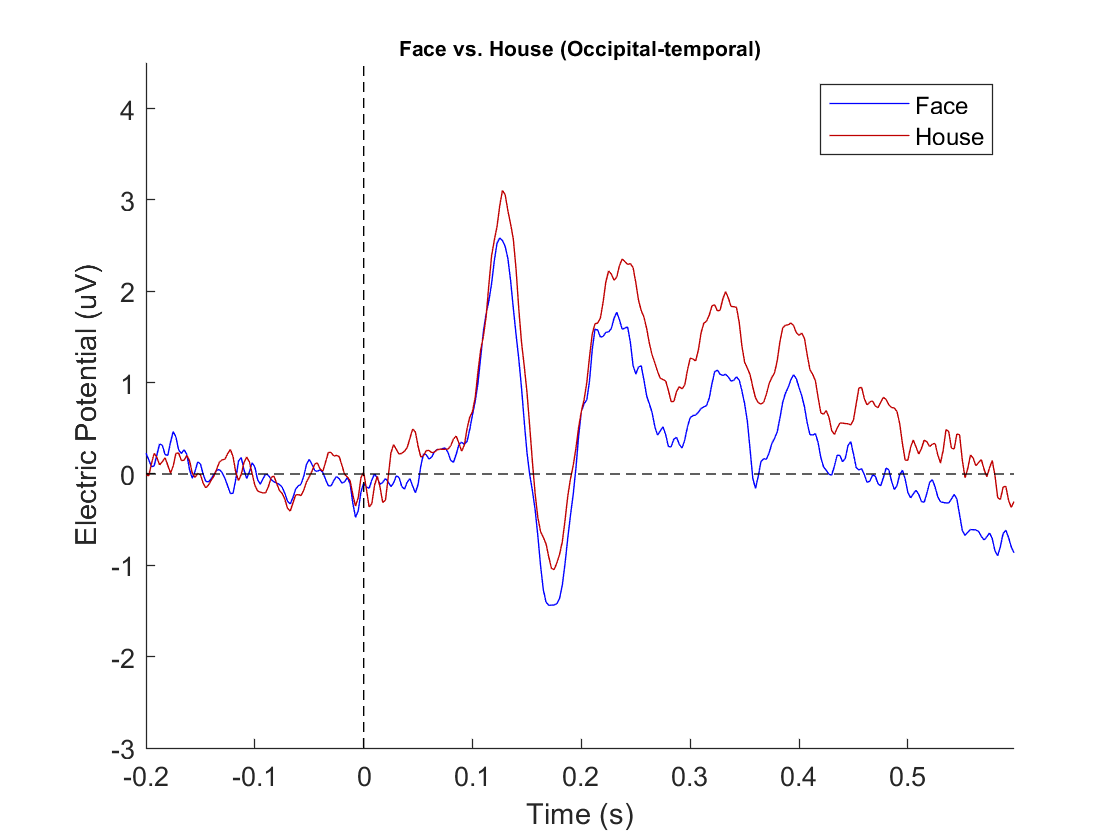

% visualize
occip_temp = {'O1', 'O2', 'Oz', 'POz','OI1h','OI2h','POO2','POO9h','POO10h','T7','T8'};
plot_ERP_func(occip_temp,erp_face,erp_house,'Face','House','Face vs. House (Occipital-temporal)',[-3 4.5]);

**Central-Frontal -> N2 (further processing or inhibition)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


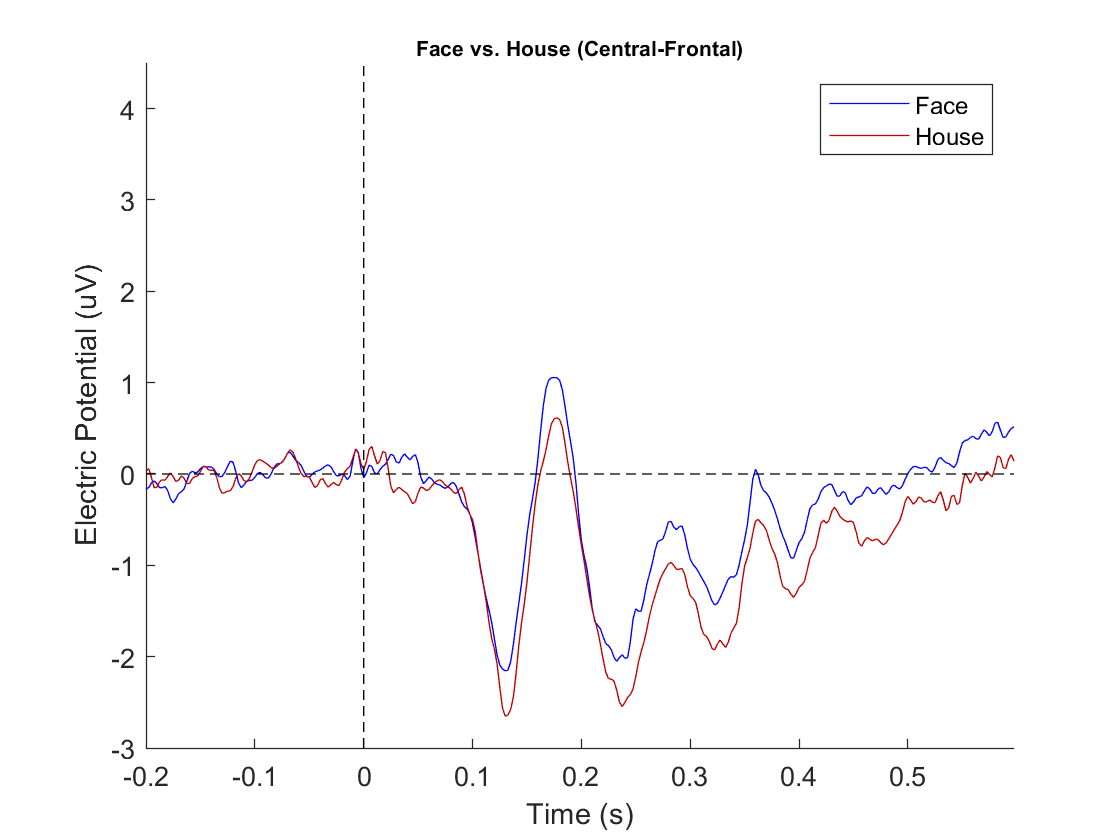

cent_front = {'FP1','FPz','FP2','AF7','AF3','AF4','AF8','F9','F7','F5','F3','F1','Fz','F2','F4','F6','F8','F10','FC5','FC3','FC1','FCz','FC2','FC4','FC6','C5','C3','C1','Cz','C2','C4','C6'};
plot_ERP_func(cent_front,erp_face,erp_house,'Face','House','Face vs. House (Central-Frontal)',[-3 4.5]);

**Central -> N400 (semantic integration)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 1 seconds


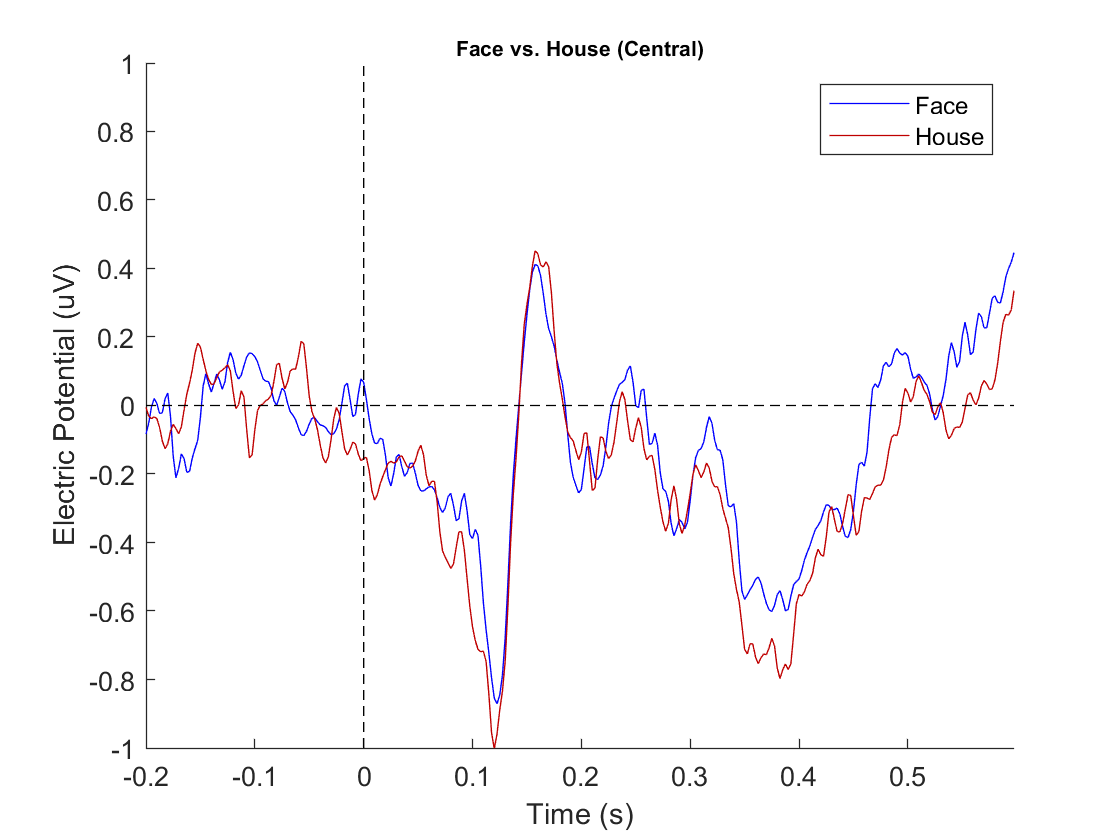

cent = {'C5','C3','C1','Cz','C2','C4','C6','FCC5h','FCC3h','FCC1h','FCC2h','FCC4h','FCC6h','CCP5h','CCP3h','CCP1h','CCP2h','CCP4h','CCP6h'};
plot_ERP_func(cent,erp_face,erp_house,'Face','House','Face vs. House (Central)',[-1 1]);

# Expected vs. Unexpected (Face)

**Visualize ERPs on the whole scalp**

ft_data1.elec.coordsys = 'eeglab';
cfg = [];
cfg.elec = ft_data1.elec;   
layout = ft_prepare_layout(cfg);

creating layout from cfg.elec
creating layout for eeg1005 system
the call to "ft_prepare_layout" took 12 seconds



cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
ft_multiplotER(cfg, erp_expected_f, erp_unexpected_f);

the call to "ft_selectdata" took 1 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 8 seconds


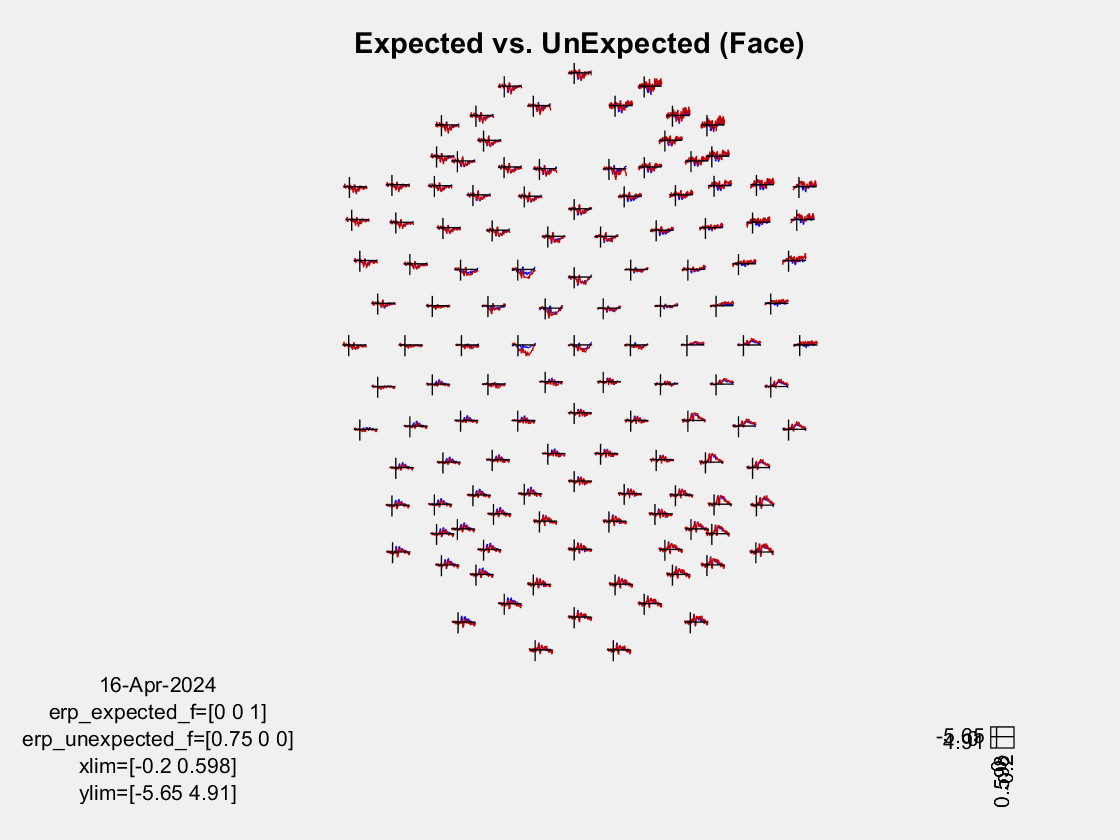

title('Expected vs. UnExpected (Face)') 

# Expected vs. Unexpected (House)

**Visualize ERPs on the whole scalp**

ft_data1.elec.coordsys = 'eeglab';
cfg = [];
cfg.elec = ft_data1.elec;   
layout = ft_prepare_layout(cfg);

creating layout from cfg.elec
creating layout for eeg1005 system
the call to "ft_prepare_layout" took 7 seconds



cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
ft_multiplotER(cfg, erp_expected_h, erp_unexpected_h);

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 5 seconds


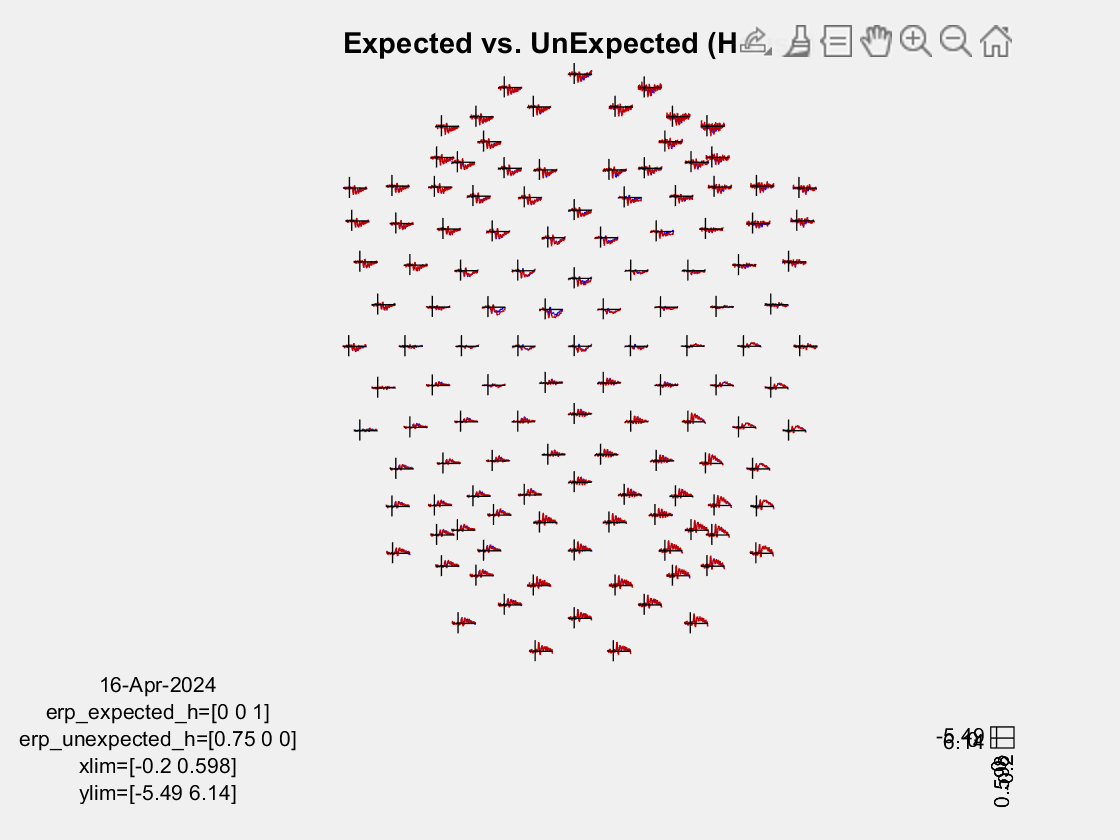

title('Expected vs. UnExpected (House)') 

**Central-Frontal Face -> MMN (Automatic Detection of Stimulus Deviance)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


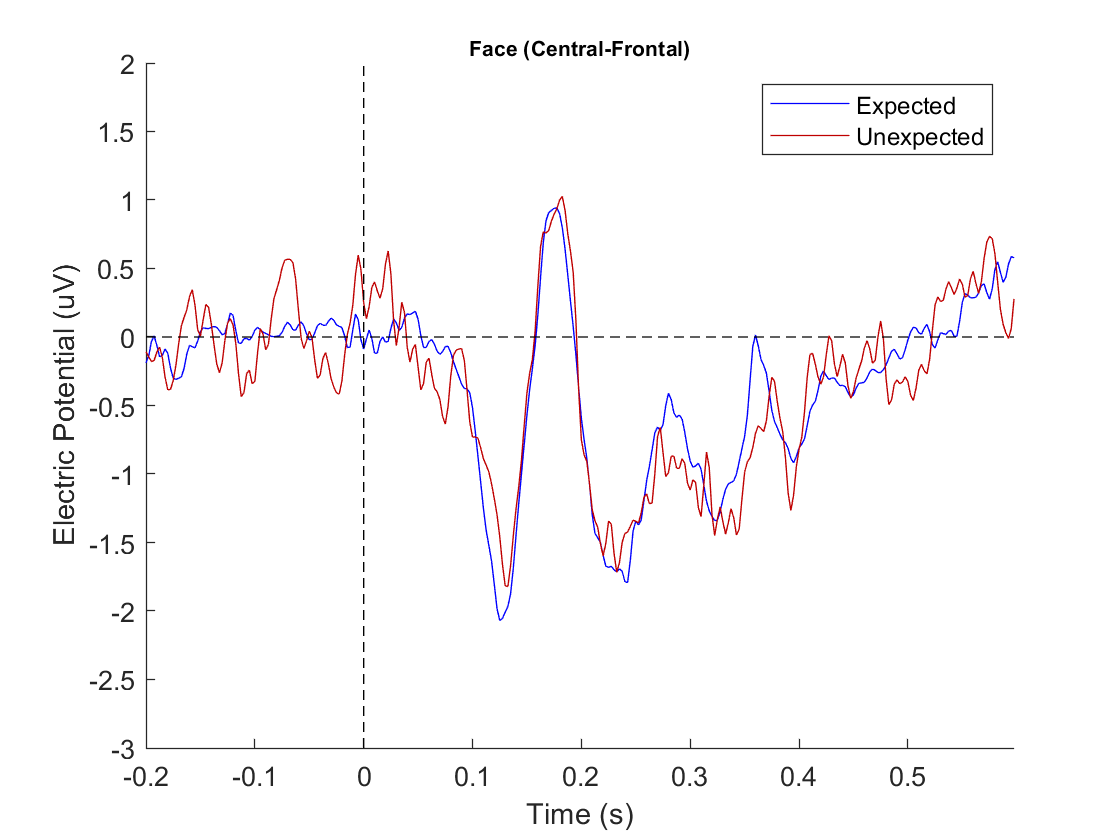

cent_front = {'FP1','FPz','FP2','AF7','AF3','AF4','AF8','F9','F7','F5','F3','F1','Fz','F2','F4','F6','F8','F10','FC5','FC3','FC1','FCz','FC2','FC4','FC6','C5','C3','C1','Cz','C2','C4','C6'};
plot_ERP_func(cent_front,erp_expected_f,erp_unexpected_f,'Expected','Unexpected','Face (Central-Frontal)',[-3 2]);

**Central-Frontal House -> MMN**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


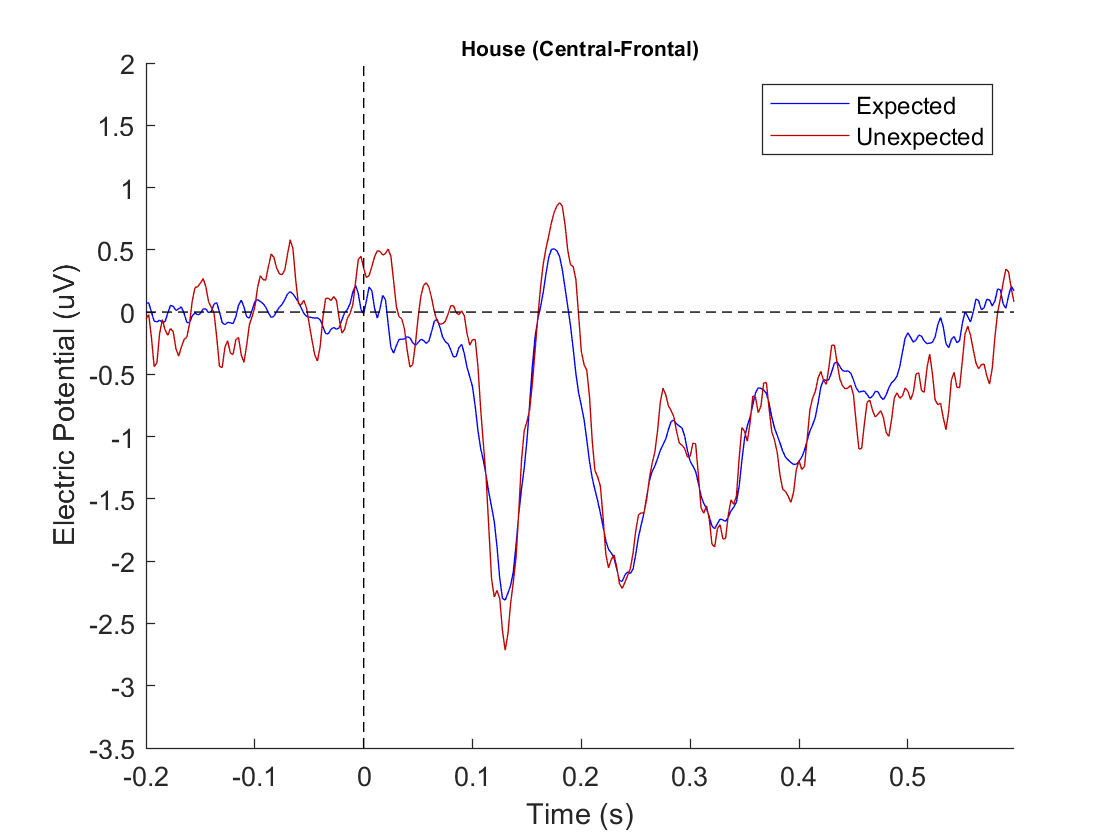

cent_front = {'FP1','FPz','FP2','AF7','AF3','AF4','AF8','F9','F7','F5','F3','F1','Fz','F2','F4','F6','F8','F10','FC5','FC3','FC1','FCz','FC2','FC4','FC6','C5','C3','C1','Cz','C2','C4','C6'};
plot_ERP_func(cent_front,erp_expected_h,erp_unexpected_h,'Expected','Unexpected','House (Central-Frontal)',[-3.5 2]);

# Repeat vs. Alternate (Face)

**Visualize ERPs on the whole scalp**


cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
ft_multiplotER(cfg, erp_repeat_f, erp_alternate_f);

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 6 seconds


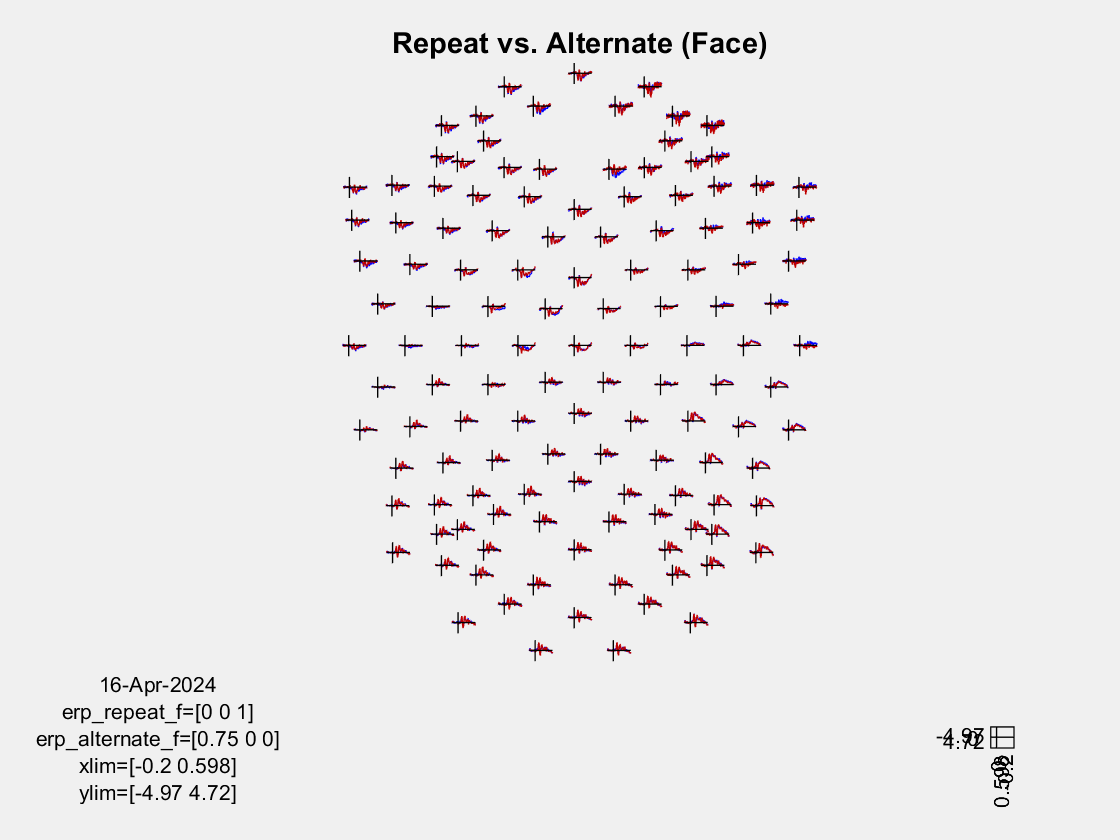

title('Repeat vs. Alternate (Face)') 

# Repeat vs. Alternate (House)

**Visualize ERPs on the whole scalp**

cfg        = [];
cfg.layout = layout;
figure;
set(gcf,'Visible','on')
ft_multiplotER(cfg, erp_repeat_h, erp_alternate_h);

the call to "ft_selectdata" took 0 seconds
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 3 seconds


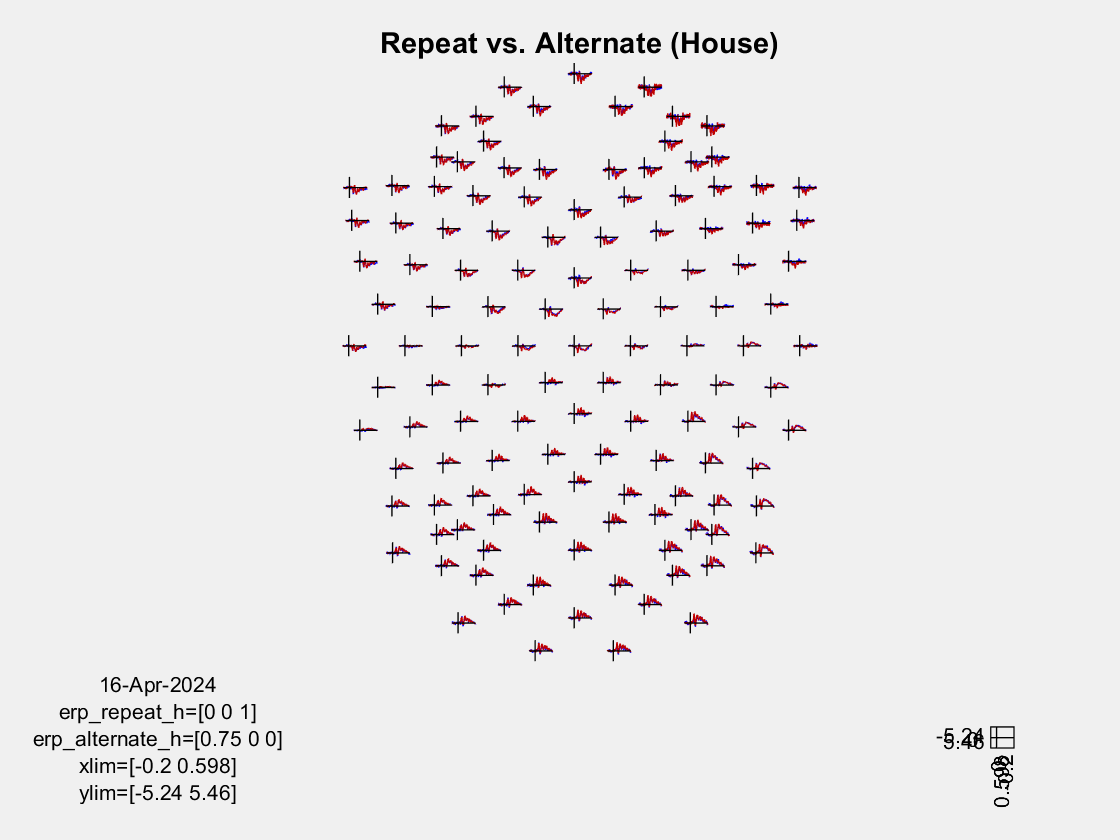

title('Repeat vs. Alternate (House)') 

**Central-Frontal Face -> MMN (Around 220 ms)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


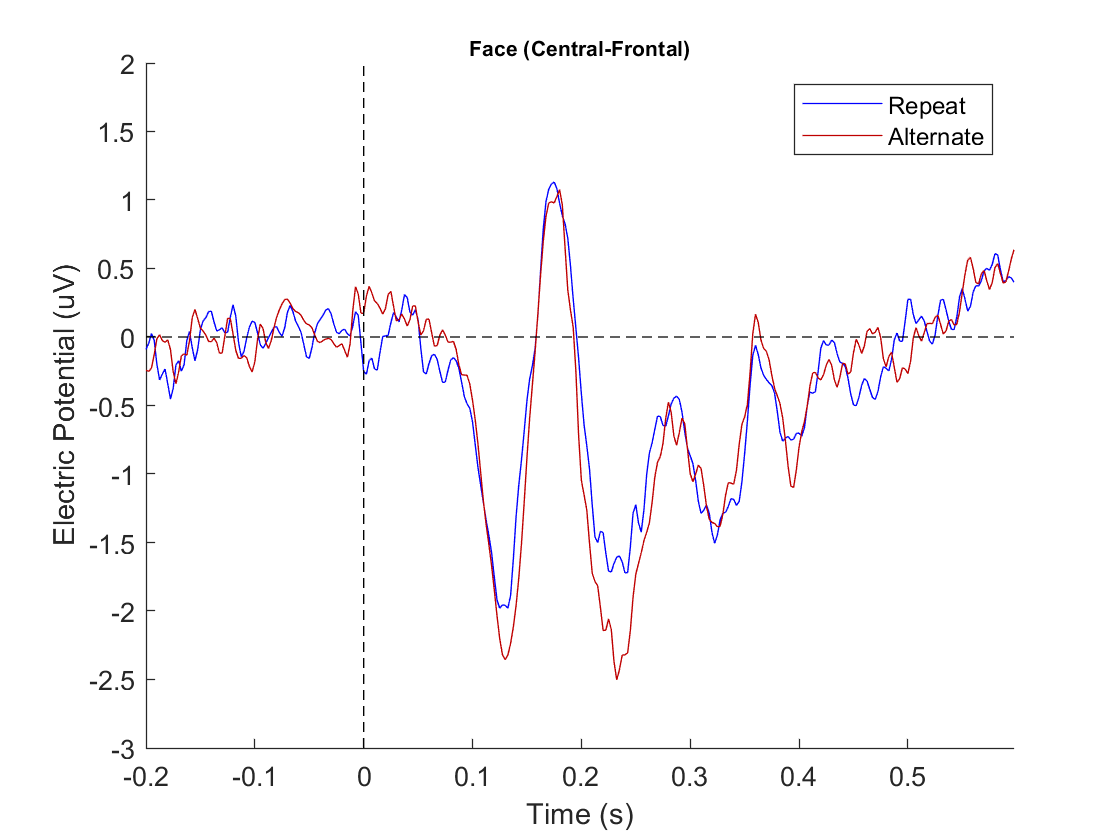

cent_front = {'FP1','FPz','FP2','AF7','AF3','AF4','AF8','F9','F7','F5','F3','F1','Fz','F2','F4','F6','F8','F10','FC5','FC3','FC1','FCz','FC2','FC4','FC6','C5','C3','C1','Cz','C2','C4','C6'};
plot_ERP_func(cent_front,erp_repeat_f,erp_alternate_f,'Repeat','Alternate','Face (Central-Frontal)',[-3 2]);

**Central-Frontal House -> MMN (Around 220 ms)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


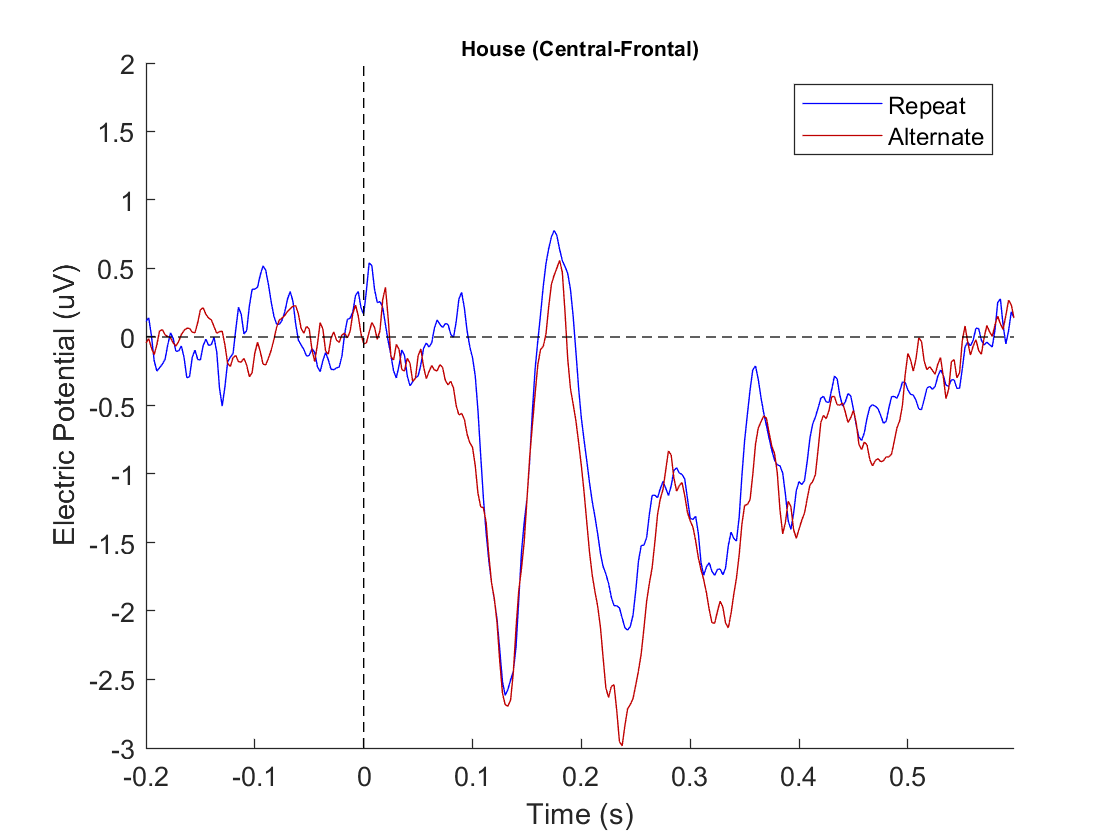

cent_front = {'FP1','FPz','FP2','AF7','AF3','AF4','AF8','F9','F7','F5','F3','F1','Fz','F2','F4','F6','F8','F10','FC5','FC3','FC1','FCz','FC2','FC4','FC6','C5','C3','C1','Cz','C2','C4','C6'};
plot_ERP_func(cent_front,erp_repeat_h,erp_alternate_h,'Repeat','Alternate','House (Central-Frontal)',[-3 2]);

**Tang et. al.'s electrodeds**

**Repetition Suppression (House)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


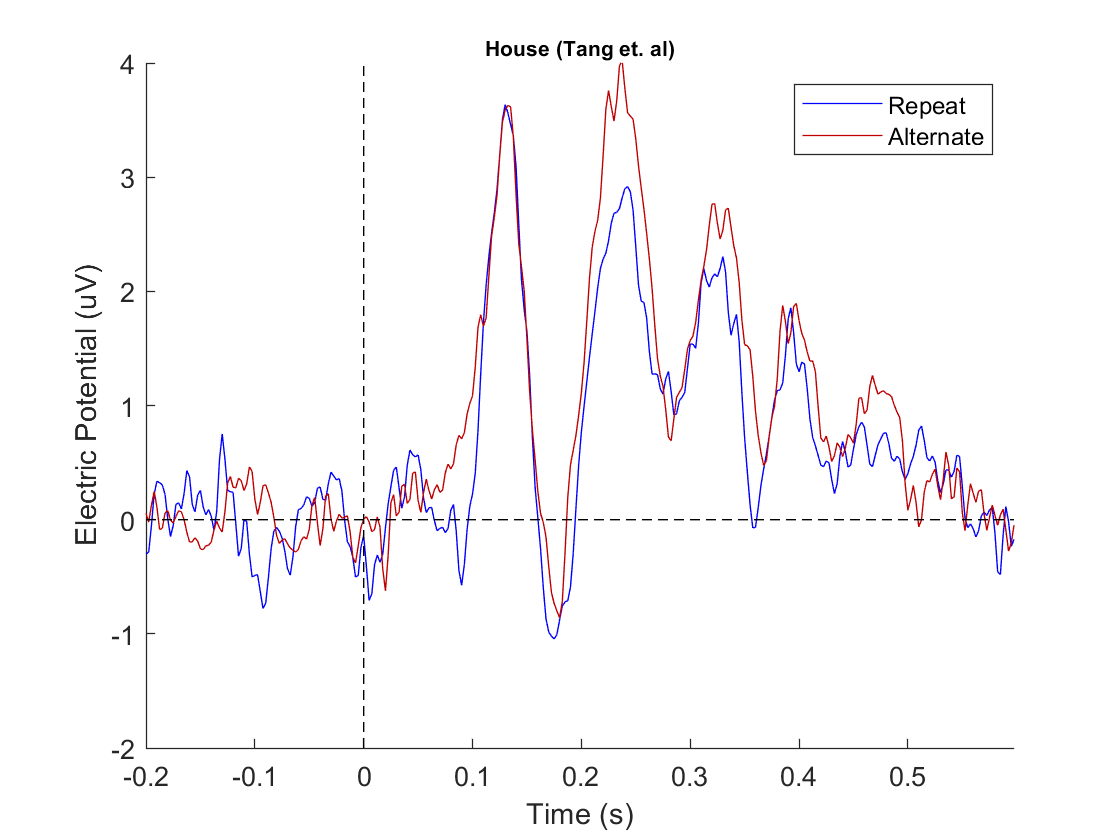

tang_et_al = {'O1', 'O2', 'Oz', 'POz', 'PO7', 'PO3', 'PO8', 'PO4', 'P3', 'Pz', 'P2'};
plot_ERP_func(tang_et_al,erp_repeat_h,erp_alternate_h,'Repeat','Alternate','House (Tang et. al)',[-2 4]);

**Repetition Suppression (Face)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


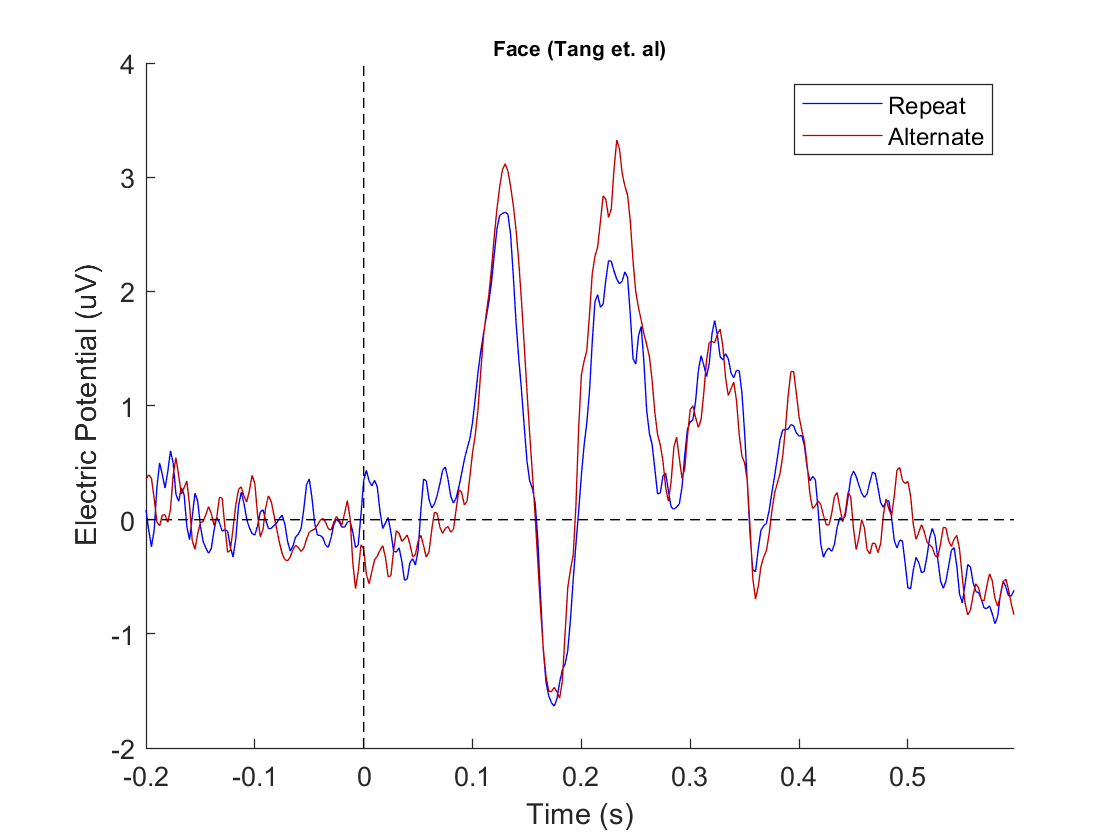

plot_ERP_func(tang_et_al,erp_repeat_f,erp_alternate_f,'Repeat','Alternate','Face (Tang et. al)',[-2 4]);

**Expectation (Face)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


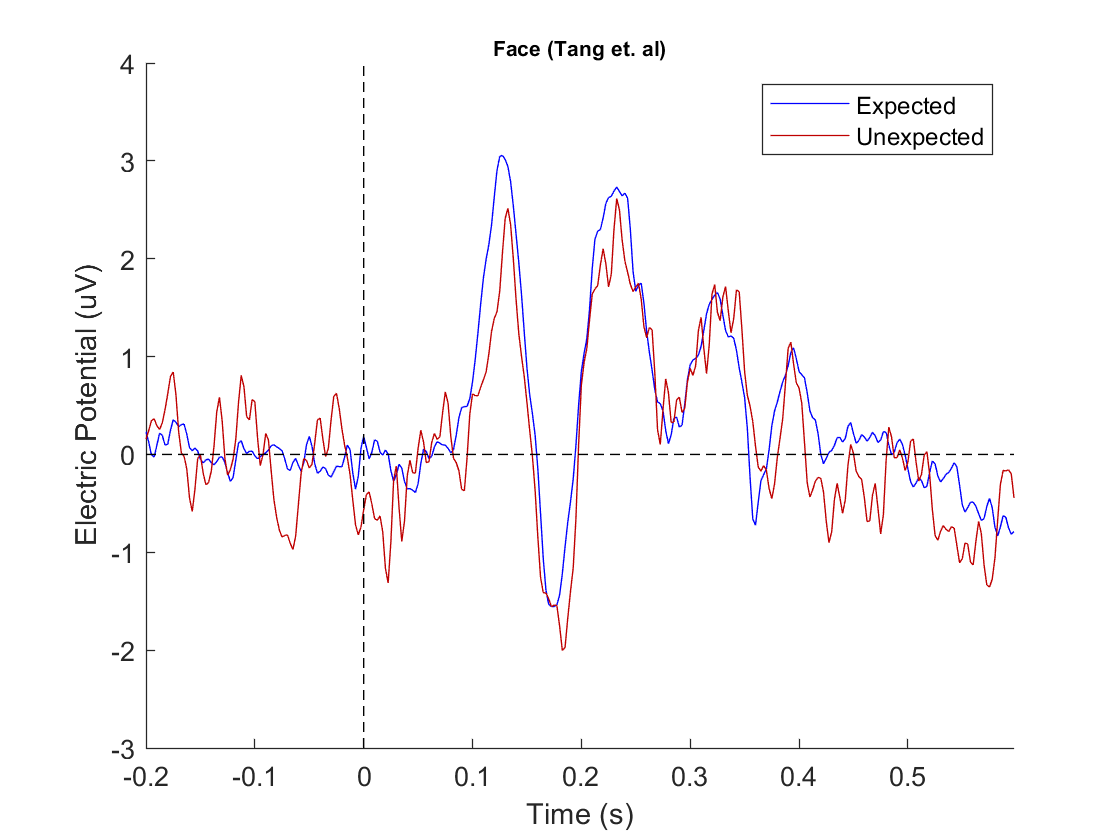

plot_ERP_func(tang_et_al,erp_expected_f,erp_unexpected_f,'Expected','Unexpected','Face (Tang et. al)',[-3 4]);

**Expectation (House)**

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotER" took 0 seconds


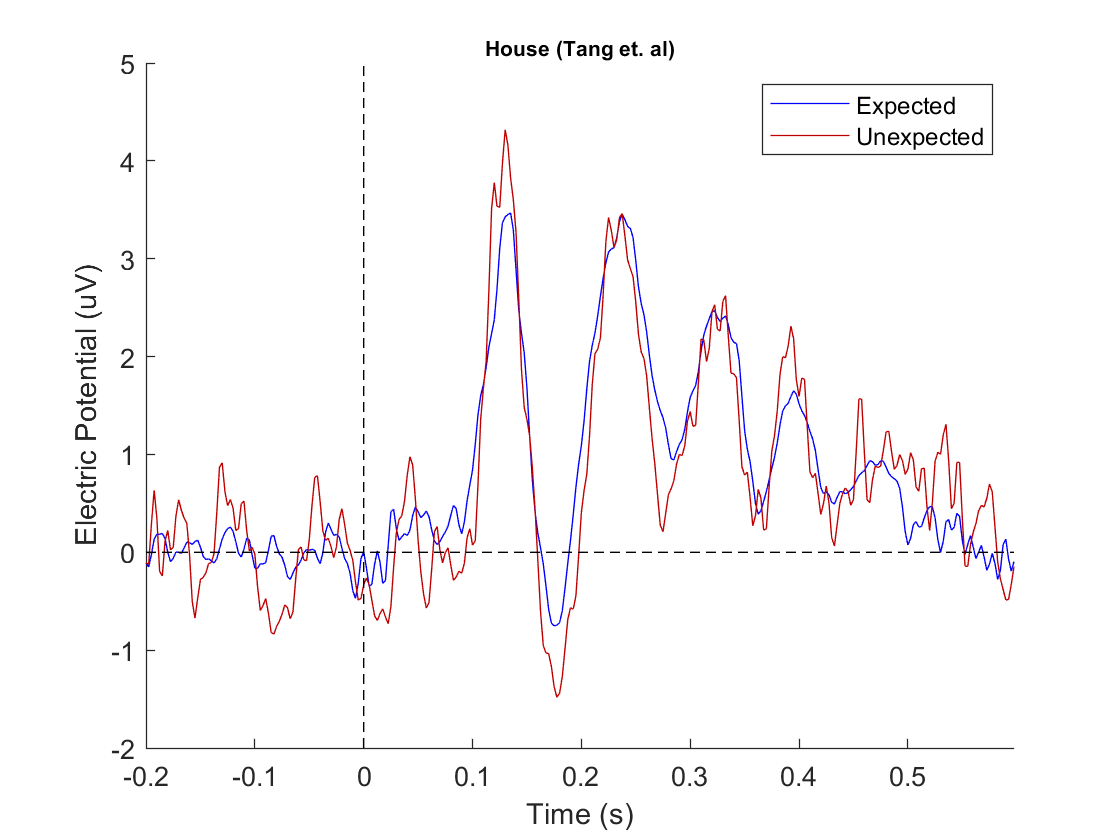

plot_ERP_func(tang_et_al,erp_expected_h,erp_unexpected_h,'Expected','Unexpected','House (Tang et. al)',[-2 5]);